## นายพิชญ์ รังษีจำรัส 62070502215    Homework 02 :

Bring up Source Image and Gray scaled it

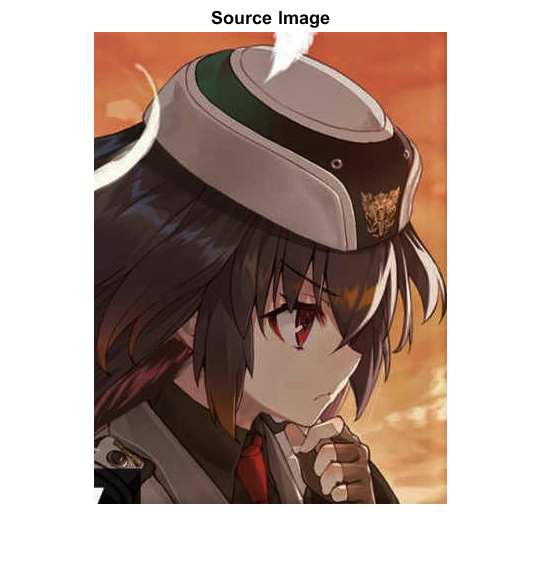

clear
clc
% input image from source
I = imread('FredericaRosenfort.jpg');
imshow(I)
title("Source Image")

% Convert rgb image to grayscale image
r = I(:,:,1);
g = I(:,:,2);
b = I(:,:,3);
I2 = (0.3*r) + (0.6*g) + (0.1*b)

I2 = 472×353 uint8 matrix
   126   127   127   127   127   128   128   128   129   128   128   129   129   128   129   131   130   130   131   131   131   131   131   132   132   131   132   133   132   132   134   137   137   137   137   137   137   137   137   139   140   140   140   140   140   140   139   139   139   137
   126   126   126   126   127   127   127   127   126   125   125   126   126   125   126   129   128   128   128   128   128   128   129   130   131   131   131   132   131   131   133   135   137   137   137   137   137   137   137   139   140   140   140   140   140   139   139   139   140   139
   127   127   126   126   126   126   126   126   126   125   125   126   125   124   126   127   127   127   128   128   127   127   128   129   130   129   129   129   128   128   131   135   137   137   137   137   136   136   137   137   139   139   139   139   139   139   139   139   140   138
   127   127   126   126   126   126   126   125   124   122   122   12

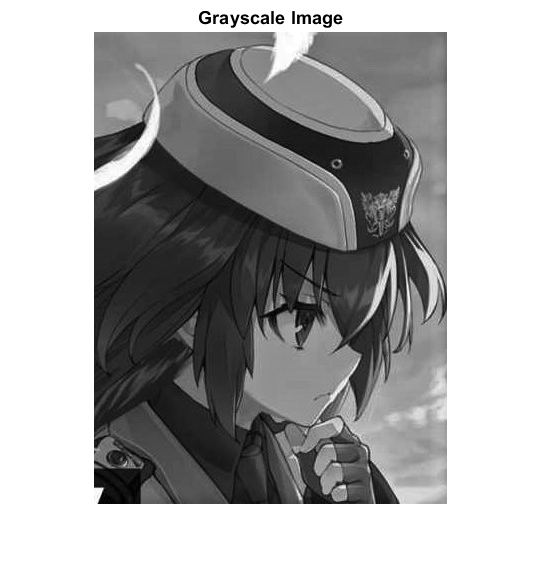

% Grayscale Image Result 
imshow(I2) 
title("Grayscale Image")

% Get image's resolution
[x y] = size(I2)

x = 472

y = 353

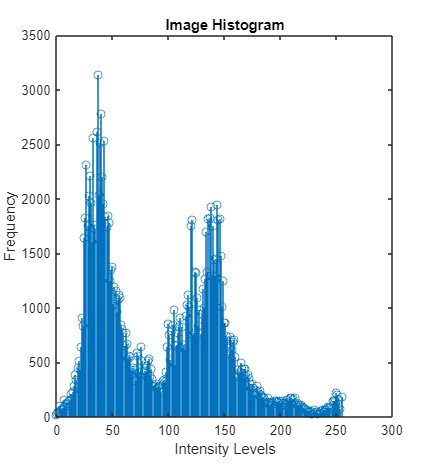

% Plot image histogram
population = zeros(1,256);
for i = 1:x 
    for j = 1:y 
            for k = 0:255
                if k == I2(i,j)
                    population(k+1) = population(k+1) + 1 ;
                end
            end
    end
end
% Histogram Result
stem(0:255,population)
title("Image Histogram")
xlabel("Intensity Levels")
ylabel("Frequency")

Write a program for automatic thresholding using

1) maximum normal line method

population % gray scale value of every pixel

population =           22          29          48         103          67          79          88         157          99         119         128         146         155         216         168         231         287         392         345         450         514         434         643         910         837        1645        1826        2313        1754        2028        2213        1964        1604        2561        1761        1728        2616        3140        2037        2518        2785        2206        1954        2534        1836        1747        1842        1785        1247        1350


%find by deriviative
deltay=[];
for l = 1:length(population)-1
    deltay(end+1) = population(l+1) - population(l);
    deltax = 1;
end
deltay(end+1) = 0 - population(256) ;
deltay %got the slope value

deltay =            7          19          55         -36          12           9          69         -58          20           9          18           9          61         -48          63          56         105         -47         105          64         -80         209         267         -73         808         181         487        -559         274         185        -249        -360         957        -800         -33         888         524       -1103         481         267        -579        -252         580        -698         -89          95         -57        -538         103          24


sign(deltay) %check for the sign of every single slope value

ans =      1     1     1    -1     1     1     1    -1     1     1     1     1     1    -1     1     1     1    -1     1     1    -1     1     1    -1     1     1     1    -1     1     1    -1    -1     1    -1    -1     1     1    -1     1     1    -1    -1     1    -1    -1     1    -1    -1     1     1


pos = [];
for z = 1:length(deltay)-1
    if sign(deltay(z+1)) == -1
        pos(end+1) = z ;
    end    
end
pos %show the position which last sign is positive before being negative

pos =      3     7    13    17    20    23    27    30    31    33    34    37    40    41    43    44    46    47    50    52    53    56    57    58    59    60    62    63    65    66    67    69    70    72    73    74    76    77    79    83    85    86    89    92    93    96   100   101   105   111


% As you can see here,the real picture didn't has only one or two intensity which  
% being last positive before going to be negative so we cannot surely know 
% that which intensity value is the top of the value by classified the 
% last positive slope value.


%find by peak max
firsthalf = []; %divided all of the intensity value into two groups
secondhalf = [];
firsthalf = population(1:127);
secondhalf = population(128:256);
[var1,col1] = max(firsthalf) ; %find the maximum value = top of the mountain
[var2,col2] = max(secondhalf) ;
col1 = col1 - 1 ;
col2 = col2+127-1 ;

var1,col1,var2,col2

var1 = 3140

col1 = 37

var2 = 1951

col2 = 144

%find the linear line equation
m = (var2-var1)/(col2-col1) %find slope

m = -11.1121

c1 = var1 - (m*col1) %find c1

c1 = 3.5511e+03

c2 = var2 - (m*col2) %find c2

c2 = 3.5511e+03

A = m

A = -11.1121

B = -1

B = -1

C = c1

C = 3.5511e+03

xline = [col1,col2];
yline = [var1,var2];

stem(0:255,population);
title("Image Histogram");
xlabel("Intensity Levels");
ylabel("Frequency");

hold on
plot(xline,yline) %plot the linear line

%find length d
d = [] ;
for posx = col1:col2
    d(end+1) = (abs((A*posx)+(B*population(posx))+C))/sqrt((A*A) + (B*B));
end
[ansy , ansx] = max(d) %get the intensity value that has maximum perpendicular line 's length

ansy = 216.9995

ansx = 36

ansx = ansx + col1 %add the start x value form col1

ansx = 73

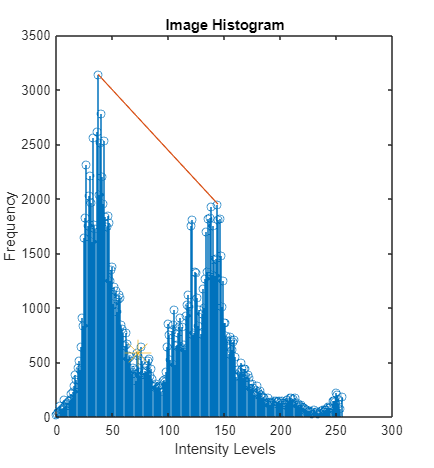

hold on
plot(ansx,population(ansx),'*','MarkerSize',20)
hold off

Th = ansx %use that value as threshold

Th = 73

3) Use threshold from maximum normal line method to change the picture to binary picture

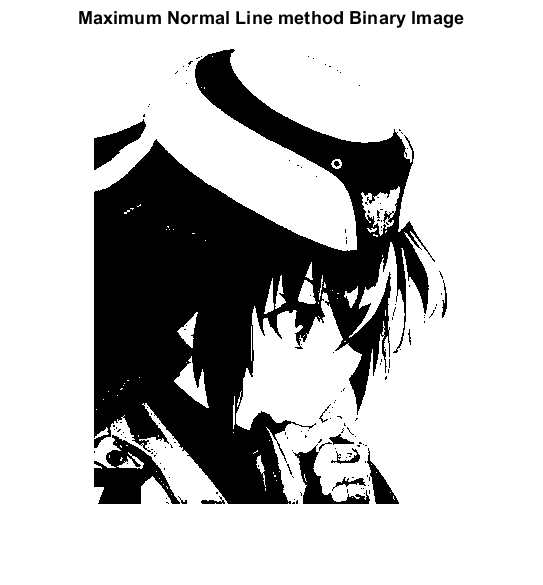

I3 = zeros(x,y);
for i = 1:x 
    for j = 1:y 
            if I2(i,j) < Th
                I3(i,j) = 0;
            else
                I3(i,j) = 1;
            end       
    end
end
% Maximum Normal Line method Binary Image Result
imshow(I3)
title("Maximum Normal Line method Binary Image")

2) average intensity method

exit = false;
a = 0; b = 255;
ranTh = a + (b-a) * rand(1) %start random

ranTh = 70.3864

Th = ranTh ;
W1 = 0.4 ; % weight1
W2 = 0.6 ; % weight2
oldTh = 0 ;


while exit == false
    G1bar = [] ;
    G2bar = [] ;
    for i = 1:x 
        for j = 1:y 
            if I2(i,j) >= Th 
                %Group1
                G1bar(end+1) = I2(i,j) ; 
            elseif I2(i,j) < Th
                %Group2
                G2bar(end+1) = I2(i,j) ;
            end       
        end
    end
    G1bar = sum(G1bar)/length(G1bar) ; %find average value of Group 1
    G2bar = sum(G2bar)/length(G2bar) ; %find average value of Group 2
    Th = ((W1*G1bar)+(W2*G2bar))/(W1+W2) ; %average intensity
    
    if abs(Th-oldTh) <= 0.01 %stop method when the new threshold different is less than 0.01
        exit = true ;
    end
    oldTh = Th ;
end
Th %use that value as threshold

Th = 80.9472

3) Use threshold from average intensity method to change the picture to binary picture

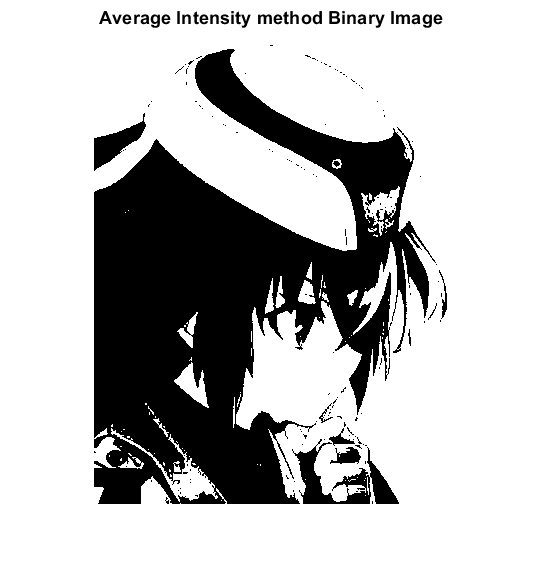

I3 = zeros(x,y);
for i = 1:x 
    for j = 1:y 
            if I2(i,j) < Th
                I3(i,j) = 0;
            else
                I3(i,j) = 1;
            end       
    end
end
% average intensity method Binary Image Result
imshow(I3);
title("Average Intensity method Binary Image")

4) Discussion of  these 2 method

4.1 - Maximum Normal Line method : เป็นวิธีที่มีการคำนวณที่ซับซ้อนกว่าและใช้เวลานานกว่า อีกทั้งยังมีข้อจำกัด ยกตัวอย่างปัญหาที่่

พบเจอคือไม่สามารถใช้การดูค่าของความชันจุดสุดท้ายก่อนเป็นค่าลบได้เพราะว่ารูปจริงๆนั้น การกระจายตัวไม่สวยเป็นภูเขาเหมือนใน

ทฤษฏี แต่มีจำนวนขึ้นๆลงๆเสมอ  จึงทำให้ค่าความชันเป็นบวกและลบสลับกันมากกว่าสองตำแหน่งที่เราต้องการจะจัดมันให้เป็นตัวแทน

ของจุดสูงสุดของข้อมูลของภูเขาสองลูกได้

4.2 Average Intensity method : เป็นวิธีที่ง่ายกว่าและรวดเร็วกว่า เป็นวิธีที่ใช้ในการทำรูปเฉดสีเทาคือถ่วงน้ำหนัก ซึ่งข้อจำกัดคือเรา

เป็นคนตั้งค่าน้ำหนักนั้นจึงอาจจะทำให้เกิดการ Bias ของข้อมูลได้ ทำให้ภาพที่ได้ในท้ายที่สุดมีความเบี่ยงเบนเกิดขึ้น 